# Introduction to MATLAB - Hands-On Workshop

Today, we will discuss how we can use MATLAB and its features to aid in data analysis. Using these features, we can manage our code better, spend more time on the actual data analysis, and improve the entire development process.

In this example, we will analyze data we gathered from a quadcopter simulation executed in Simulink. Quadcopters are notoriously difficult environments for collecting good sensor data. Quadcopters typically have on-board IMU sensors, comprised of 3 gyroscopes and 3 accelerometers. Any type of autonomous flight requires using this sensor data to estimate a full state (position, velocity, Euler angles, angular rates). This difficulty of this task increases greatly if the sensor data is noisy.

Unfortunately, most quadcopters rely on low-cost sensors due to their affordability, which tend to exhibit higher levels of noise compared to the more expensive sensors used in the aviation industry. Furthermore, the quadcopter's airframe itself exacerbates the issue of sensor noise. The presence of 4 motors rotating 4 propellers at very high RPM (up to 30,000 RPM in this example) generates vibrations in the airframe that can contaminate the sensor data.

The objective of this flight test data analysis is to examine the IMU data and determine the characteristics of the sensor noise for implementing a Kalman filter sensor fusion algorithm. It is crucial to separate the sensor noise from the airframe vibration in the data to achieve accurate results.

## Setup

addpath("App/","Data/","HelperFunctions/");
run config.m

## Part 0: Live Scripts

Let us explore this document. This .mlx file is a [Live Script](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html). Live Scripts are interactive documents that combine MATLAB code with formatted text, equations, and images in a single environment called the Live Editor. Let's try recreating the image of the equation below:

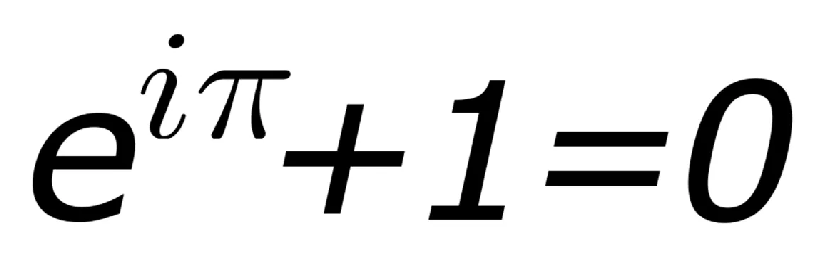

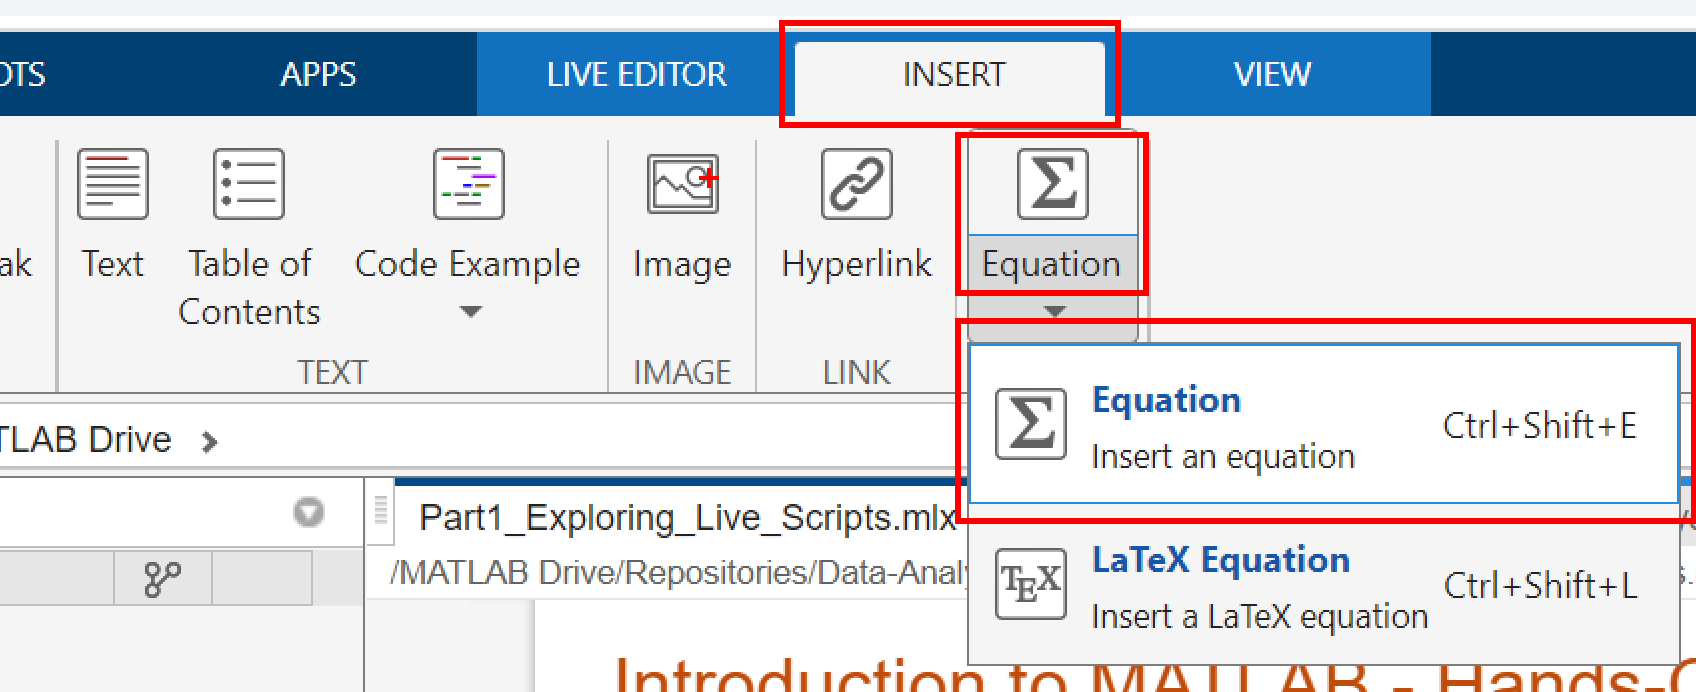

Written Equation: 

We can also use Live Scripts to: 

- Easily build reports

- Utilize unique features like [live controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) and [live tasks](https://www.mathworks.com/help/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html) in th "Live Editor" toolstrip

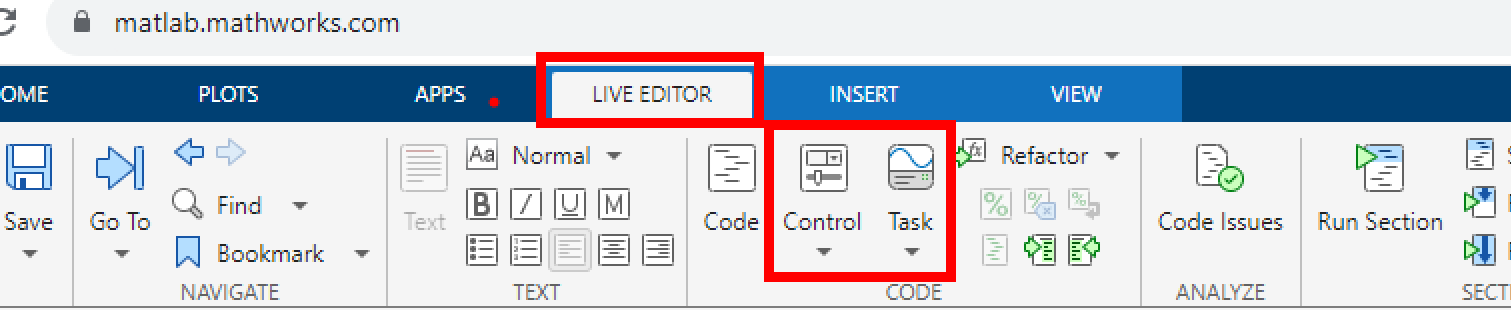

if true
    disp("I have been checked")
end

I have been checked



tempData = randi(1000,100,1);

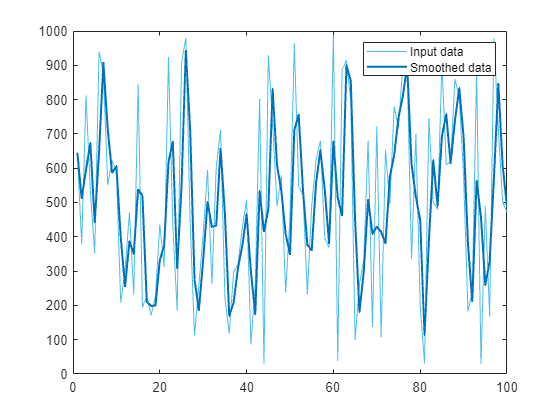

% Smooth input data
smoothedData2 = smoothdata(tempData,"movmean","SmoothingFactor",0.25);

% Display results
figure
plot(tempData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

- Interact with your data and plots more intuitively in the "Figure" toolstrip

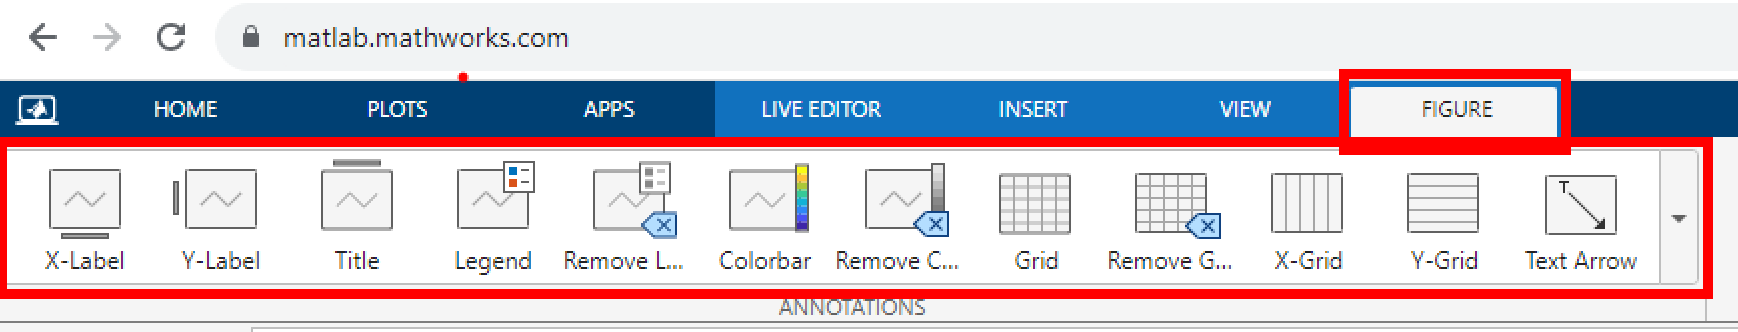

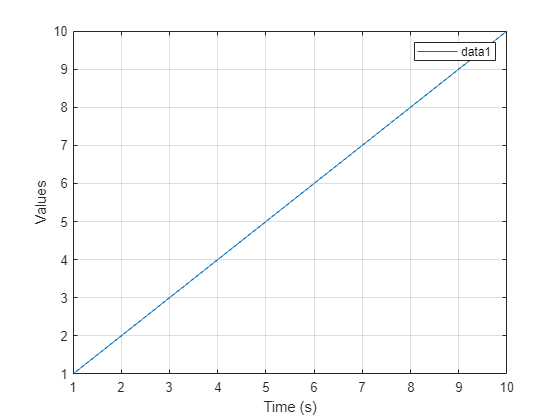

plot(1:10)

grid on
legend("show")
xlabel("Time (s)")
ylabel("Values")

clear tempData

## Part 1: Analyze Flight Data - Access Input Data Using Import Tool App

We can use the [Import Tool](https://www.mathworks.com/help/matlab/import_export/import-data-interactively.html) in MATLAB to import data from a file into MATLAB interactively. 

### **Step 1: Open the Tool and Select the Practice File**

In the "Home" toolstrip, select the **Import Data** icon. Open the data file "***Data/practiceData.csv" ***first. Let's explore some features of the Import Tool. 

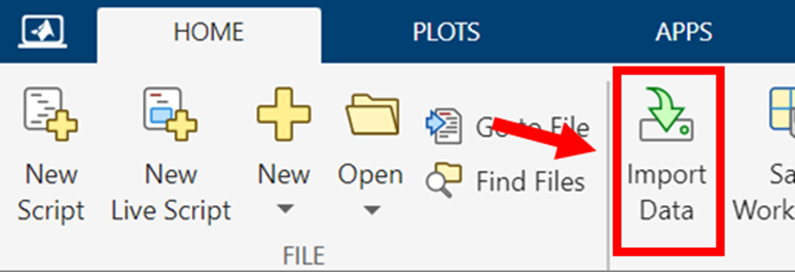

### Step 2: Select and Edit the Data To Import

One feature is the ability to directly import data into our workspace after we have selected our data. You can select the data by clicking the cells you want to import. If you want to import a whole cell or row, select the row number or column header. Re-selecting an already selected option will de-select the option.

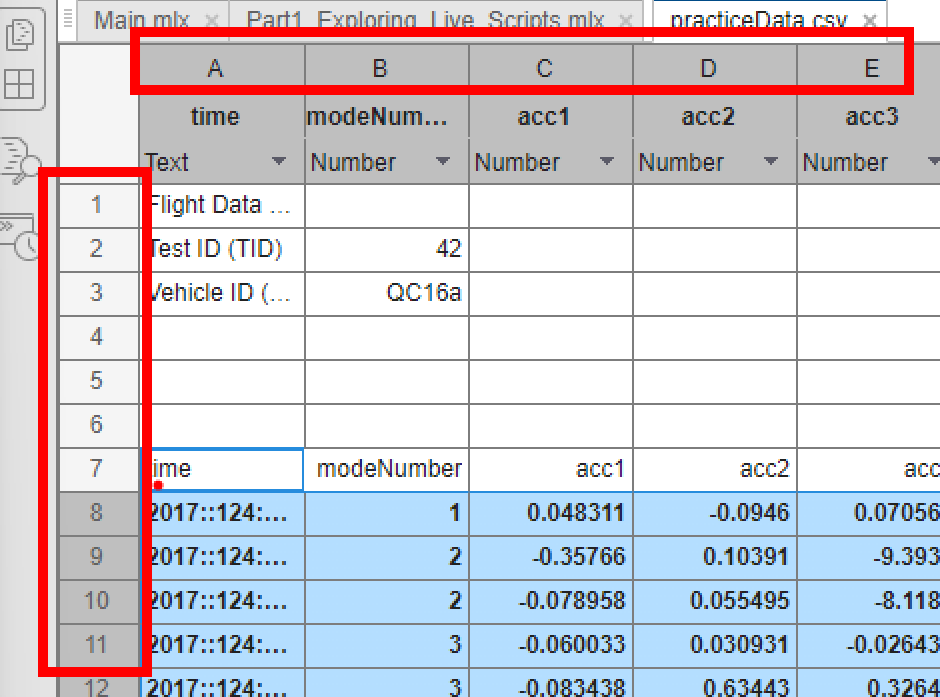

*****Please Note**: ***The data starts from Row 8 and the Column Names can be found in Row 7. We need to reflect these changes in the Import Tool before importing in any data.

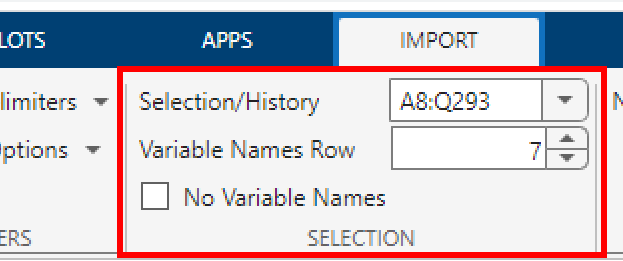

### Step 3: Create a Function To Automate Data Import And Save It

We saw how we can import our data directly into the workspace. This may not be convenient if we have many files. Note that after setting up the App to import the data, you can instead select the option to **Generate Function**. This will automatically create a MATLAB function that will replicate the data import as performed through the App. We can then **save** this function to use in the future.

*****Please Note**: ***The name of the function and the name of the file must match. Click [here](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html) for more information on creating MATLAB functions and MATLAB function calling syntax.

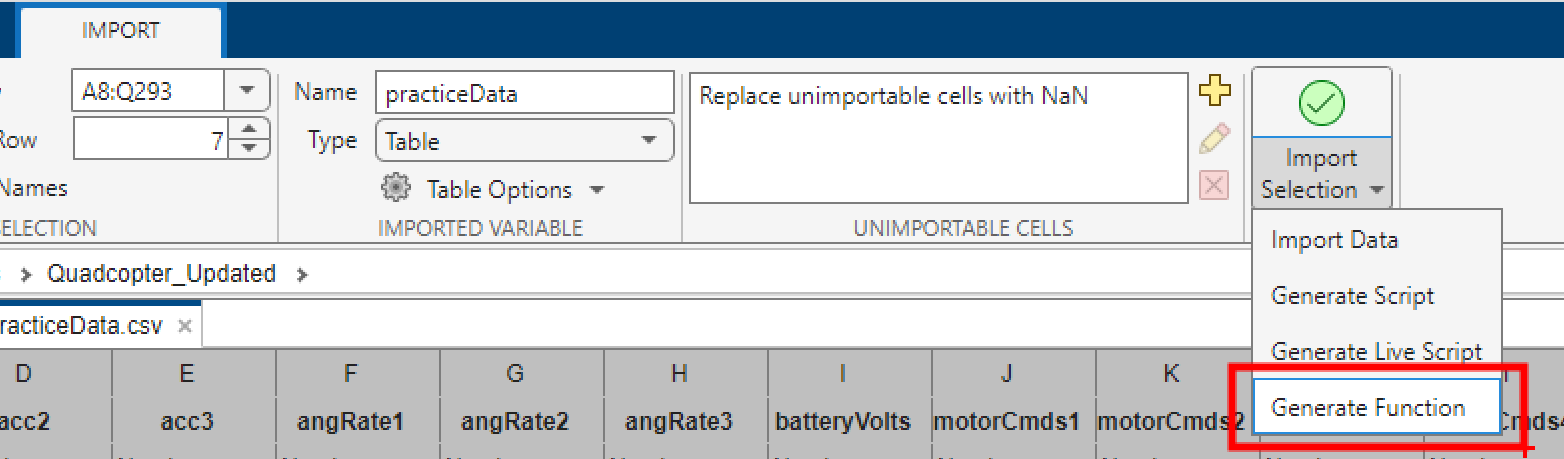

### Step 4: Import a New Dataset Using Our Actual Data File

Let's create a new variable, **"myData"**, and use our newly-generated function from earlier to pull in our final dataset ***"Data/flightData.csv"*****.**

*****Please Note**:*** The syntax for variable names, inputs/outputs, and function name is **case-sensitive.**

myData = importfile("flightData.csv");

We will convert time from string format to "[datetime](https://www.mathworks.com/help/matlab/ref/datetime.html)" format since we are working with time-series data.

myData.time = datetime(myData.time,'Format', 'u::DDD:HH:mm:ss.SS');

## Part 2: Analyze Flight Data - Visualize

### Step 1: Open the Data in the Variable Editor

Let's visualize our data by exploring our options in the plots gallery. We can open up our data by double clicking on our **"myData" **variable in our workspace. This will open the "Variables" toolstrip where we can select some data we want to visualize. Let's select "time" and "acc1". 

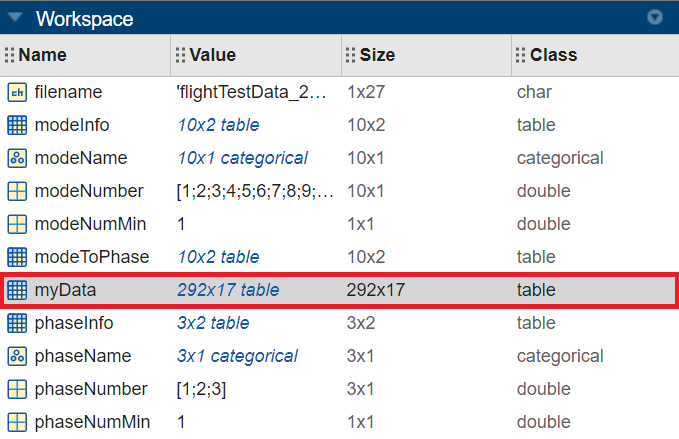

### Step 2: Create a Plot of the Data

Once the data is selected, let's plot it and customize it. We can select a plot in the "Variable" toolstrip.

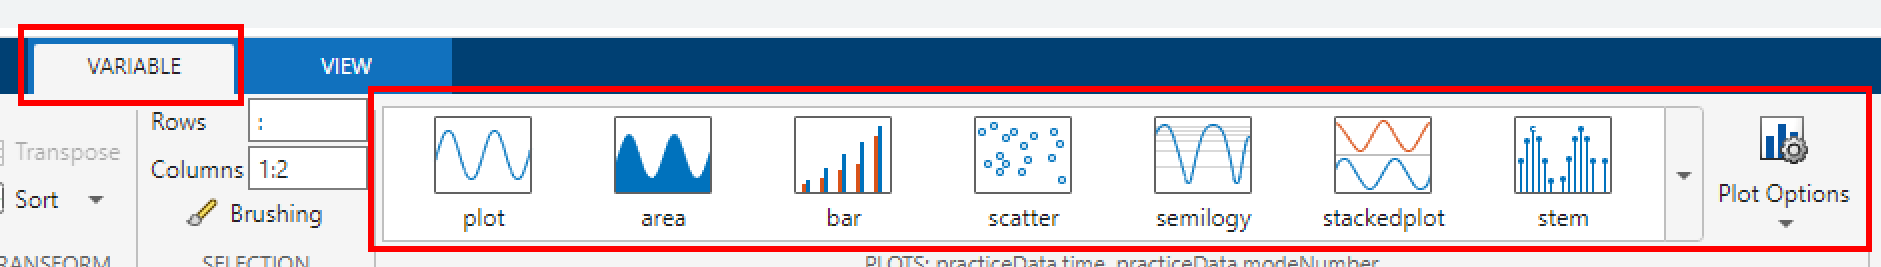

### Step 3: Edit and Customize the Plot

Let's customize our plot interactively and make it more informative. To do this, we can eplore the options found in the "Figure", "Format", and "Tools" toolstrips.

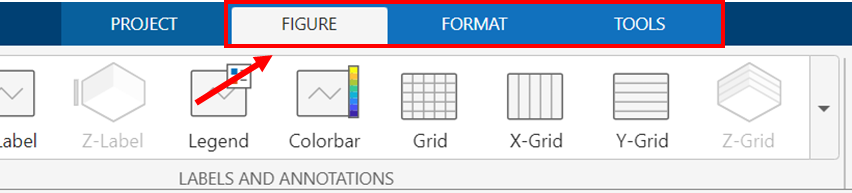

### **Step 4: **Create a Function To Automate Data Visualization

Again, we want to automate this process so let's use the option to **Generate Function **found in the "Tools" toolstrip.

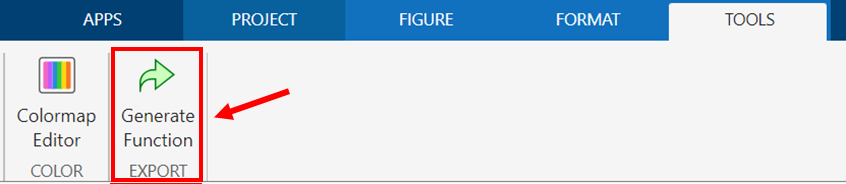

Practice calling the newly created plot function below. You can use the myData variable created in the previous activity.

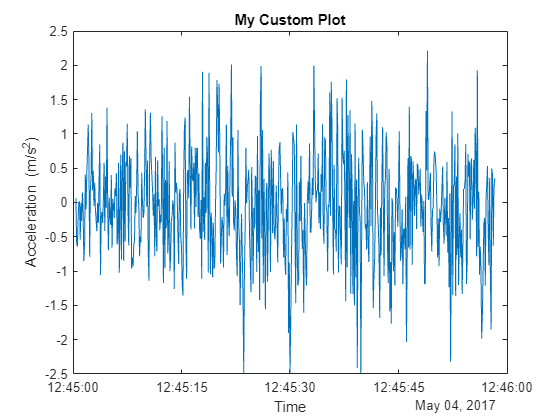

createfigure(myData.time,myData.acc1)

Let's take a look at some examples extending this capability.

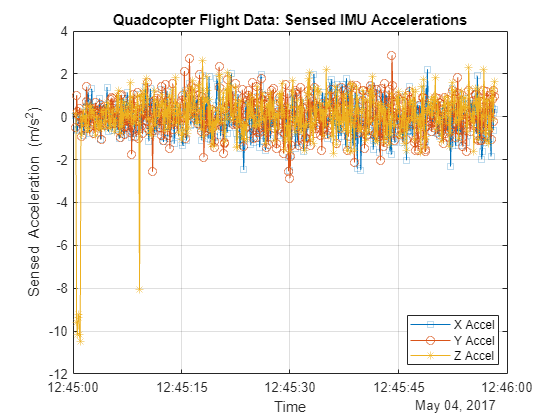

%IMU Data: Translational Acceleration
plotIMUaccels(myData.time, [myData.acc1 myData.acc2 myData.acc3])

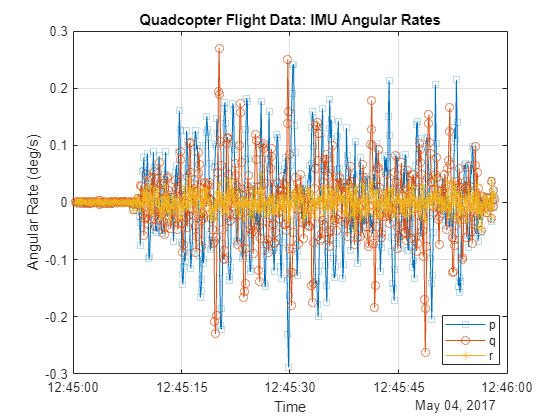

%IMU Data: Angular Rates
plotAngRates(myData.time, [myData.angRate1 myData.angRate2 myData.angRate3])

## Further Analysis (Optional): Supporting Multiple Plots in One Figure

The plots above are a little messy so let's use individual plots for each axis. Here, we will use the new '[tiledlayout](https://www.mathworks.com/help/matlab/ref/tiledlayout.html)' option to re-plot our IMU data in the X, Y, and Z axes. 

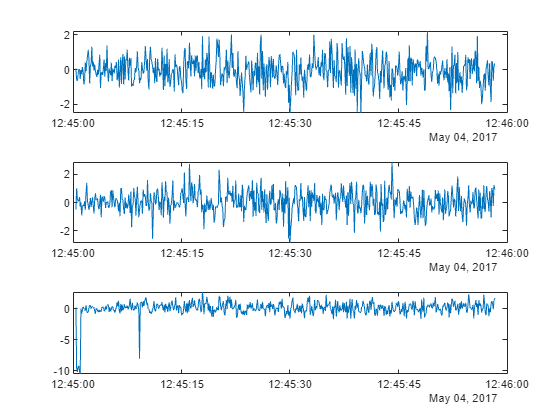

figure()
tiledlayout(3,1);
x = myData.time; 
y1 = myData.acc1;
y2 = myData.acc2;
y3 = myData.acc3;

% Tile 1
nexttile
plot(x,y1)

% Tile 2
nexttile
plot(x,y2)

% Tile 3
nexttile
plot(x,y3)

## Further Analysis (Optional): Analyze Flight Data - Logical Indexing

Logical indexing in MATLAB is a powerful approach for finding subsets of data within a large data set that meets certain criteria.

Specify all rows where mode number is 6 (Track Altitude Mode).

tempIdx = myData.modeNumber == 6

idxMode6c = 580×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Let's see a comparison of different methods to see how efficient we can get!

%method 1
tic;
idxMode6a = []; 
for i = 1:height(myData)
    if myData.modeNumber(i) == 6
        idxMode6a(end+1) = i;
    end
end
toc

Elapsed time is 0.004587 seconds.



%method 2
tic;
idxMode6b = find(myData.modeNumber == 6);
toc

Elapsed time is 0.002570 seconds.



%method 3
tic;
idxMode6c = myData.modeNumber == 6;
toc

Elapsed time is 0.001725 seconds.


idx6Data = myData(idxMode6c,:)

idx6Data = 6×17 table
            time             modeNumber      acc1         acc2         acc3       angRate1      angRate2      angRate3      batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1        pos2          pos3       isBallFlag
    _____________________    __________    _________    _________    ________    __________    __________    ___________    ____________    __________    __________    __________    __________    _______   

## Further Analysis (Optional): Analyze Flight Data - Timetables

Using the right tool for the right job can really help speed up analysis. Here, we will explore the benefits of using a '[timetable](https://www.mathworks.com/help/matlab/timetables.html)' in MATLAB. 'timetables' have many built-in capabilities that make working with time-series data faster and quicker. Let's explore.

dataTable = myData;
dataStruct = table2struct(myData);
myData = table2timetable(myData);
whos dataTable dataStruct myData

  Name              Size              Bytes  Class        Attributes

  dataStruct      580x1             1126288  struct                 
  dataTable       580x17              83467  table                  
  myData          580x16              83253  timetable              



**A)  Identify Events**

We can easily find and isolate events based on external criteria using an '[eventtable](https://www.mathworks.com/help/matlab/matlab_prog/find-events-in-timetable-using-event-table.html#FindEventsInTimestampedDataExample-2)'. Let's try an example of finding all troughs in our IMU data in the Z-axis. **(**to go through interval events in hyperlink)**

troughs = find(islocalmin(myData.acc3));
typeLabels = categorical([ones(size(troughs))], 1, "trough");
extremaEvents = extractevents(myData, troughs,EventLabels=typeLabels)

extremaEvents = 183×1 eventtable
  Event Labels Variable: EventLabels
  Event Lengths Variable: <instantaneous>

            time             EventLabels
    _____________________    ___________

    2017::124:12:45:00.60      trough   
    2017::124:12:45:01.00      trough   
    2017::124:12:45:01.20      trough   
    2017::124:12:45:01.70      trough   
    2017::124:12:45:02.00      trough   
    2017::124:12:45:02.50      trough   
    2017::124:12:45:03.10      trough   
    2017::124:12:45:03.50      trough   
    2017::124:12:45:03.70      trough   
    2017::124:12:45:03.90      trough   
    2017::124:12:45:04.10      trough   
    2017::124:12:45:04.39      trough   
    2017::124:12:45:04.60

**B)  Isolate a minute around timestamp 2017::124:12:45:60.00**

We can easily isolate a certain tolerance of time around a specific event. Lets isolate a minute around the first trough event we notice from earlier.

tol = withtol(datetime('2017::124:12:45:00.60','Format', 'u::DDD:HH:mm:ss.SS'), minutes(1))

tol = 	timetable withtol subscript:

		Select timetable rows matching the following times:

		2017::124:12:45:00.60
		with tolerance of +/- 1 min

	See Select Times in Timetable.


myData(tol,:)

ans = 580×16 timetable
            time             modeNumber       acc1         acc2          acc3        angRate1       angRate2      angRate3      batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1       pos2       pos3      isBallFlag
    _____________________    __________    __________    _________    __________    ___________    __________    ___________    ____________    __________    __________    __________    __________    _______

**C)  Join Tables/Timetables together**

We need to gather data corresponding to each of the Operational Phases. The simple approach is model where each **Mode** maps to a single **Phase** (1:1 relationship). 

modeInfo

modeInfo = 10×2 table
    modeNumber      modeName  
    __________    ____________

         1        WaitForComms
         2        Init        
         3        Calibration 
         4        ReadyForTO  
         5        TakeOff     
         6        TrackAlt    
         7        Track3D     
         8        LostBall    
         9        Land        
        10        EmergencyOff


phaseInfo

phaseInfo = 3×2 table
    phaseNumber     phaseName  
    ___________    ____________

         1         GroundRotOff
         2         GroundRotOn 
         3         InFlight    


modeToPhase

modeToPhase = 10×2 table
    phaseNumber     phaseName  
    ___________    ____________

         1         GroundRotOff
         1         GroundRotOff
         1         GroundRotOff
         2         GroundRotOn 
         3         InFlight    
         3         InFlight    
         3         InFlight    
         3         InFlight    
         3         InFlight    
         1         GroundRotOff


Append Phase Number and Phase Name columns to modeInfo table (

modeInfo.phaseNumbers = modeToPhase{:,1};
modeInfo.phaseNames = modeToPhase{:,2};
modeInfo

modeInfo = 10×4 table
    modeNumber      modeName      phaseNumbers     phaseNames 
    __________    ____________    ____________    ____________

         1        WaitForComms         1          GroundRotOff
         2        Init                 1          GroundRotOff
         3        Calibration          1          GroundRotOff
         4        ReadyForTO           2          GroundRotOn 
         5        TakeOff              3          InFlight    
         6        TrackAlt             3          InFlight    
         7        Track3D              3          InFlight    
         8        LostBall             3          InFlight    
         9        Land                 3          InFlight    
        10        EmergencyOff         1          GroundRotOff


% Join tables
joinedData = join(myData,modeInfo,"Keys","modeNumber")

joinedData = 580×19 timetable
            time             modeNumber       acc1         acc2          acc3        angRate1       angRate2      angRate3      batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1       pos2       pos3      isBallFlag      modeName      phaseNumbers     phaseNames 
    _____________________    __________    __________    _________    __________    ___________    __________    ___________    ____________    __________    __

myData = join(myData,modeInfo,'Keys','modeNumber')

myData = 580×19 timetable
            time             modeNumber       acc1         acc2          acc3        angRate1       angRate2      angRate3      batteryVolts    motorCmds1    motorCmds2    motorCmds3    motorCmds4     pos1       pos2       pos3      isBallFlag      modeName      phaseNumbers     phaseNames 
    _____________________    __________    __________    _________    __________    ___________    __________    ___________    ____________    __________    ______

## Further Analysis (Optional): Outlier Detection Using Live Tasks

**On Ground: Rotor Blades Off**

*Calculate Statistics for Linear Acceleration*

%Generate table of data when Flight  Phase equals "GroundRotOff"
RawGroundRotOff = myData(myData.phaseNames == "GroundRotOff",:);
statsRawGroundRotOff = table();

%Average
statsRawGroundRotOff.Average  =  mean( [  ...
                                                RawGroundRotOff.acc1...
                                                RawGroundRotOff.acc2...
                                                RawGroundRotOff.acc3...
                                                RawGroundRotOff.angRate1...
                                                RawGroundRotOff.angRate2...
                                                RawGroundRotOff.angRate3 ] )' ;
%Standard Deviation                                       
statsRawGroundRotOff.Sigma    =  std( [  ...
                                                RawGroundRotOff.acc1...
                                                RawGroundRotOff.acc2...
                                                RawGroundRotOff.acc3...
                                                RawGroundRotOff.angRate1...
                                                RawGroundRotOff.angRate2...
                                                RawGroundRotOff.angRate3  ] )' ;
%Maximum                                            
statsRawGroundRotOff.Maximum   =  max( [  ...
                                                RawGroundRotOff.acc1...
                                                RawGroundRotOff.acc2...
                                                RawGroundRotOff.acc3...
                                                RawGroundRotOff.angRate1...
                                                RawGroundRotOff.angRate2...
                                                RawGroundRotOff.angRate3  ] )' ; 
                                            
%Minimum                                                
statsRawGroundRotOff.Minimum   =  min( [  ...  
                                                RawGroundRotOff.acc1...
                                                RawGroundRotOff.acc2...
                                                RawGroundRotOff.acc3...
                                                RawGroundRotOff.angRate1...
                                                RawGroundRotOff.angRate2...
                                                RawGroundRotOff.angRate3  ] )' ;                                           
                                       
%RowNames of the Table
statsRawGroundRotOff.Properties.RowNames = {'acc1' 'acc2' 'acc3' 'angRate1' 'angRate2' 'angRate3'};        

**On Ground: Rotor Blades On**

*Calculate Statistics for Linear Acceleration*

RawGroundRotOn   = myData(myData.phaseNames == "GroundRotOn",:);
statsRawGroundRotOn = table();

%Average
statsRawGroundRotOn.Average  =  mean( [  RawGroundRotOn.acc1 ...
                                            RawGroundRotOn.acc2 ...
                                            RawGroundRotOn.acc3...
                                            RawGroundRotOn.angRate1...
                                            RawGroundRotOn.angRate2...
                                            RawGroundRotOn.angRate3  ] )' ;
                                                
%Standard Deviation                                       
statsRawGroundRotOn.Sigma    =  std( [   RawGroundRotOn.acc1...
                                            RawGroundRotOn.acc2...
                                            RawGroundRotOn.acc3...
                                            RawGroundRotOn.angRate1...
                                            RawGroundRotOn.angRate2...
                                            RawGroundRotOn.angRate3   ] )' ;
                                                
%Maximum                                            
statsRawGroundRotOn.Maximum   =  max( [  RawGroundRotOn.acc1...
                                            RawGroundRotOn.acc2...
                                            RawGroundRotOn.acc3...
                                            RawGroundRotOn.angRate1...
                                            RawGroundRotOn.angRate2...
                                            RawGroundRotOn.angRate3   ] )' ; 
                                                
                                            
%Minimum                                                
statsRawGroundRotOn.Minimum   =  min( [  RawGroundRotOn.acc1...
                                            RawGroundRotOn.acc2...
                                            RawGroundRotOn.acc3...
                                            RawGroundRotOn.angRate1...
                                            RawGroundRotOn.angRate2...
                                            RawGroundRotOn.angRate3   ] )' ;                                             
                                       
%RowNames of the Table
statsRawGroundRotOn.Properties.RowNames = {'acc1' 'acc2' 'acc3' 'angRate1' 'angRate2' 'angRate3'};        

**In Flight**

*IMU Acceleration Statistics during Flight Phase #3 - In Flight (Rotors ON)*

RawInFlight = myData(myData.phaseNames == "InFlight",:);
statsRawInFlight = table();

statsRawInFlight.Average =   mean ( [ RawInFlight.acc1...
                                         RawInFlight.acc2...
                                         RawInFlight.acc3...
                                         RawInFlight.angRate1...
                                         RawInFlight.angRate2...
                                         RawInFlight.angRate3   ] )' ;

                                       
statsRawInFlight.Sigma  =  std ( [    RawInFlight.acc1...
                                         RawInFlight.acc2...
                                         RawInFlight.acc3...
                                         RawInFlight.angRate1...
                                         RawInFlight.angRate2...
                                         RawInFlight.angRate3 ] )' ;
                                           
%Maximum                                            
statsRawInFlight.Maximum  =  max ( [  RawInFlight.acc1...
                                         RawInFlight.acc2...
                                         RawInFlight.acc3...
                                         RawInFlight.angRate1...
                                         RawInFlight.angRate2...
                                         RawInFlight.angRate3 ] )' ;  
                                                
                                            
%Minimum                                                
statsRawInFlight.Minimum  =  min ( [  RawInFlight.acc1...
                                         RawInFlight.acc2...
                                         RawInFlight.acc3...
                                         RawInFlight.angRate1...
                                         RawInFlight.angRate2...
                                         RawInFlight.angRate3 ] )' ;   
                                                                                                                                
%RowNames of the Table
statsRawInFlight.Properties.RowNames = {'acc1' 'acc2' 'acc3' 'angRate1' 'angRate2' 'angRate3'};        

**Statistics for IMU Acceleration for Each Phase of Flight**

**Phase 1: On Ground with Rotors OFF**

statsRawGroundRotOff

statsRawGroundRotOff = 6×4 table
                  Average        Sigma       Maximum      Minimum  
                ___________    _________    _________    __________

    acc1           0.032553      0.55327       1.3826       -1.0574
    acc2             0.0378      0.49734       1.3939       -1.0491
    acc3           -0.73705       2.7047       1.5786       -10.505
    angRate1    -0.00021922    0.0014737    0.0024617    -0.0042611
    angRate2     0.00026512    0.0011632    0.0026282    -0.0027142
    angRate3     0.00018186    0.0013238    0.0038337    -0.0026653


Does this make sense? Why is the sigma for the acceleration in the Z-axis so large? Let's plot the data real quick to see what's going on...

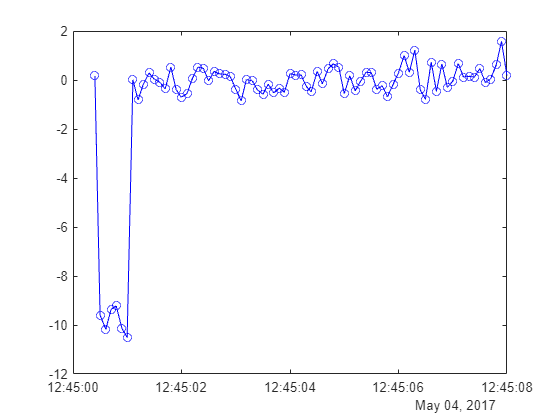

figure
plot(RawGroundRotOff.time, RawGroundRotOff.acc3, 'o-b');

Before the onboard calibration is complete, we see gravity in the raw Z-axis of the IMU accelerometer data. Once the calibration routine begins, we can see this bias being subtracted out. This is distorting our statistics and we have a few options to deal with the distortion:

- Treat the uncalibrated data points as outliers

- Ignore all data until calibration is complete

- Subtract out the known gravity bias where it is polluting the data

For now, let's use option 1. We can do this in a live task.

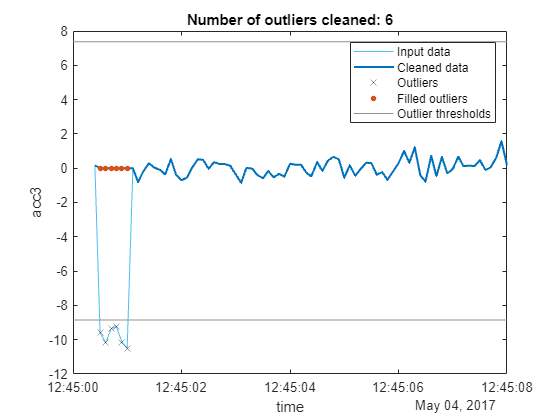

% Fill outliers
[newTable,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(RawGroundRotOff,"next","mean","DataVariables","acc3");

% Display results
figure
plot(RawGroundRotOff.time,RawGroundRotOff.acc3,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(RawGroundRotOff.time,newTable.acc3,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(RawGroundRotOff.time(outlierIndices(:,4)),RawGroundRotOff.acc3(outlierIndices(:,4)),...
    "x","Color",[64 64 64]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(RawGroundRotOff.time(outlierIndices(:,4)),newTable.acc3(outlierIndices(:,4)),".",...
    "MarkerSize",12,"Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow.acc3*[1 1] NaN thresholdHigh.acc3*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,4)))
legend
ylabel("acc3")
xlabel("time")

clear thresholdLow thresholdHigh

## Part 3: Share Results and Generate Report

Now that we have run a basic analysis of our data and removed any potential noise, let's create a report so we can document this work. To create a document, you can go into **Live Editor > Save > Export To... **and choose what type of document you want to export this Live Script to.